# Second Order System

rng(1,'twister');

## Define plant

% define state matrix
A = rand(2);
B = rand(2);
C = rand(2);
D = rand(2);

### Calculate raw plant

% make state space obj
plant = ss(A,B,C,D);
plant.InputName = {'u1','u2'};
plant.OutputName = {'y_1','y_2'};
plant.StateName = {'x_1','x_2'};

open_loop_report_raw = test_plant(plant);

G = tf(plant);

### Calculate augmented plant with state output

Ca = [C;eye(size(C))];
Da = [D;zeros(size(C,1),size(D,2))];
plant_aug = ss(A,B,Ca,Da);
plant_aug.InputName = {'u1','u2'};
plant_aug.OutputName = {'y_1','y_2','x_1','x_2'};
plant_aug.StateName = {'x_1','x_2'};

G_aug = tf(plant_aug);

open_loop_report_aug = test_plant(plant_aug);

## Calculate Controller's

### Calculate LQR controller

Q_provided = diag([10,5]);
R_provided = diag([2,2]);

[K,S,e] = lqr(plant,Q_provided,R_provided,zeros(size(A,1),size(B,1)));

LQR_control = ss(0,zeros(1,2),zeros(2,1),K);
LQR_control.InputName = {'x_1','x_2'};
LQR_control.StateName = {'fake'};
LQR_control.OutputName = {'u1','u2'};

plant_CL = feedback(plant_aug,LQR_control,'name',-1);

G_CL = tf(plant_CL);

closed_loop_report = test_plant(plant_CL);

### How good was LQR

cl_settling_time = [closed_loop_report.stepinfo.SettlingTime]

cl_settling_time =    13.9671   11.3460   11.8474    5.6564   12.6869   16.5834   15.9562    3.6434


ol_settling_time = [open_loop_report_raw.stepinfo.SettlingTime]

ol_settling_time =    NaN   NaN   NaN   NaN


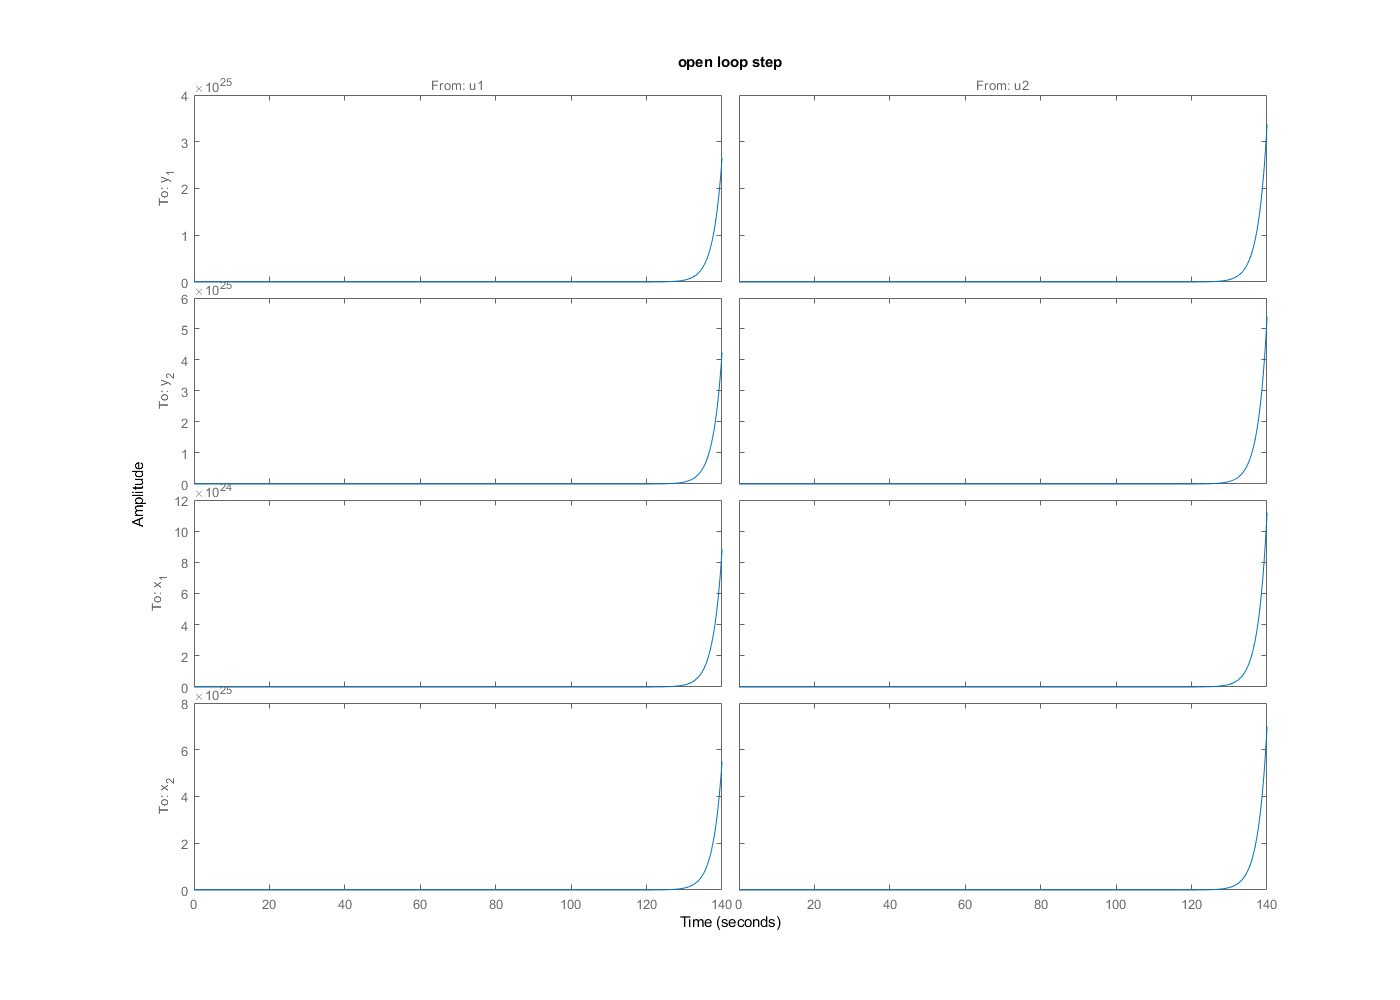


step(plant_aug)
title('open loop step');

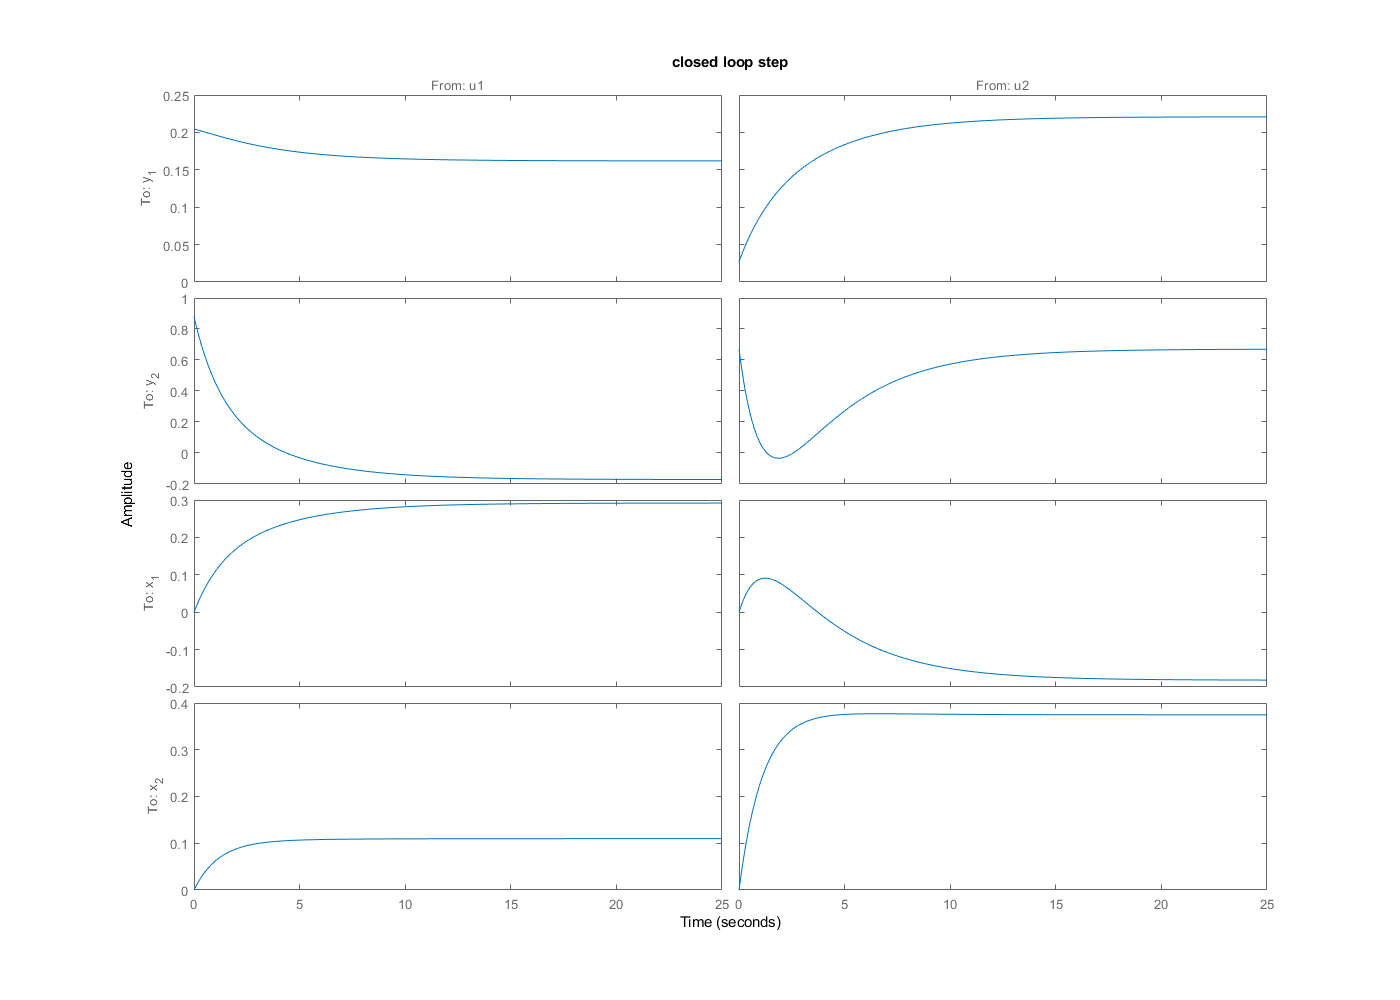

step(plant_CL)
title('closed loop step');

### Calculate Hinf controller

## Utility Functions

### Evaluate plant

function report = test_plant(plant)

report.stepinfo = stepinfo(plant);
try
    report.HistSettlingTime = histogram(report.stepinfo.SettlingTime);
catch ME
    report.HistSettlingTime = ME.message;
end
report.nyquistPlot = nyquist(plant);
[p,z]=pzmap(plant);
report.systemPoles = p;
report.systemZeros = z;

end